clear
close all
format compact
clc

## Simulation Params

t_stop = 30;
wd = (2*pi/0.05)/10;


$$Z_C = \sqrt{\frac{z}{y}} = \sqrt{\frac{L_l}{C_l}} = \frac{1}{kg\omega} = \frac{2 \omega^3}{g^2 \rho}$$


## Characteristic Impedance Taylor Expansion (Even-Order)

Express the wave characteristic impedance $Z_C(\omega )$ using even powers of ω, by expanding around ω₀ up to 4th order.

### Taylor Expansion Expression

The original impedance is:


$$Z_C(\omega) = \frac{2\omega^3}{g^2 \rho}$$


Rewriting this as a function of $\( x = \omega^2 \)$, we get:


$$Z_C(x) = \frac{2x^{3/2}}{g^2 \rho} \quad \text{where } x = \omega^2$$


The Taylor expansion of $\( x^{3/2} \)
$ around $\( x_0 = \omega_0^2 \)$ gives:


$$x^{3/2} \approx x_0^{3/2} + \frac{3}{2}x_0^{1/2}(x - x_0) + \frac{3}{8}x_0^{-1/2}(x - x_0)^2$$


Substituting back $\( x = \omega^2 \)$, we obtain:


$$Z_C(\omega) \approx A_0 + A_2 \omega^2 + A_4 \omega^4$$


### **Coefficients**

The coefficients are:


$$A_0 = -\frac{\omega_0^3}{4 g^2 \rho}
$$



$$
A_2 = \frac{3\omega_0}{2 g^2 \rho}
$$



$$
A_4 = \frac{3}{4 g^2 \rho \omega_0}$$


### Final Approximation Expression

Thus, the even-order approximation of $\( Z_C(\omega) \)$ becomes:


$$Z_C(\omega) \approx -\frac{\omega_0^3}{4 g^2 \rho} + \frac{3\omega_0}{2 g^2 \rho} \omega^2 + \frac{3}{4 g^2 \rho \omega_0} \omega^4$$


% Propagation model params

A = 1;
T = 10;
pi_length = 10;
rho = 1000;
g = 9.8;
w = 2*pi/T;
c = g/w;
lambda = g*T^2/(2*pi);
P = rho*g^2/(16*w)*(2*A)^2

P = 3.8213e+04

Vrms = A*w/sqrt(2)  % deta/dt

Vrms = 0.4443

d_eta_pk = A*w;

ZC = 2*w^3/(g^2*rho)

ZC = 5.1656e-06

Cl = rho*g/(2*w^2);
Ll = 2*w^4/(rho*g^3);
z = 1i*w*Ll;
y = 1i*w*Cl;
gamma = sqrt(z*y)

gamma = 0.0000 + 0.0403i

Z = z*pi_length;
Y = y*pi_length;

expected_phase_shift = pi_length/lambda*360

expected_phase_shift = 23.0811


L_lumped = Z/(1i*w)

L_lumped = 3.3119e-06

C_lumped = Y/(1i*w)/2

C_lumped = 6.2059e+04


L = L_lumped;
C = C_lumped;
SIL = ZC;

% Parameters
omega0 = 0.125 * 2*pi; % expansion point (rad/s)

% Frequency range
omega = linspace(0, 2*omega0, 500);

% Original characteristic impedance
Z_true = (2 .* omega.^3) ./ (g^2 * rho);

% Taylor expansion coefficients (even-order around omega0)
A0 = -omega0^3 / (4 * g^2 * rho);
A2 = (3 * omega0) / (2 * g^2 * rho);
A4 = 3 / (4 * g^2 * rho * omega0);

% Taylor approximation
Z_approx = A0 + A2 .* omega.^2 + A4 .* omega.^4;

tf_SIL = [A4 0 -A2 0 A0];

% Define the transfer function as the inverse
epsilon = 1e-3;
sys = tf(1, tf_SIL + [0 0 0 0 epsilon]);  % Add small epsilon to avoid division by near-zero
poles=pole(sys);

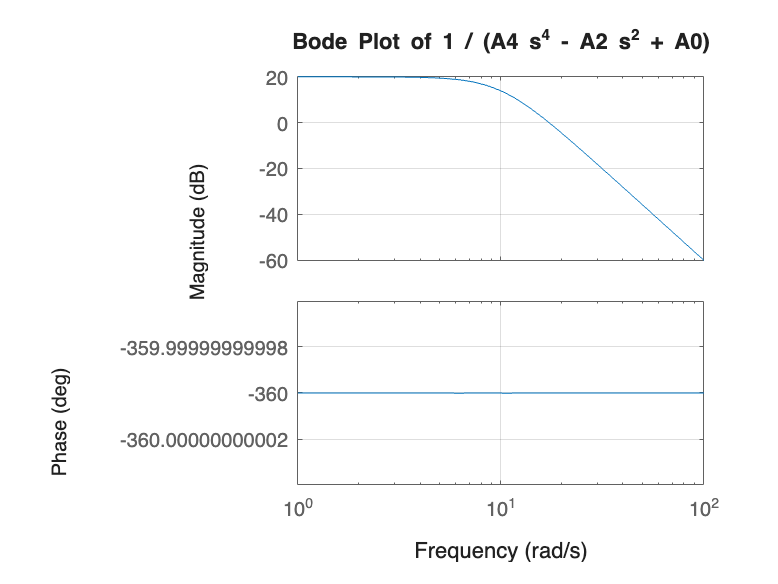

% Bode plot
figure
bodeplot(sys)
grid on;
title('Bode Plot of 1 / (A4 s^4 - A2 s^2 + A0)');

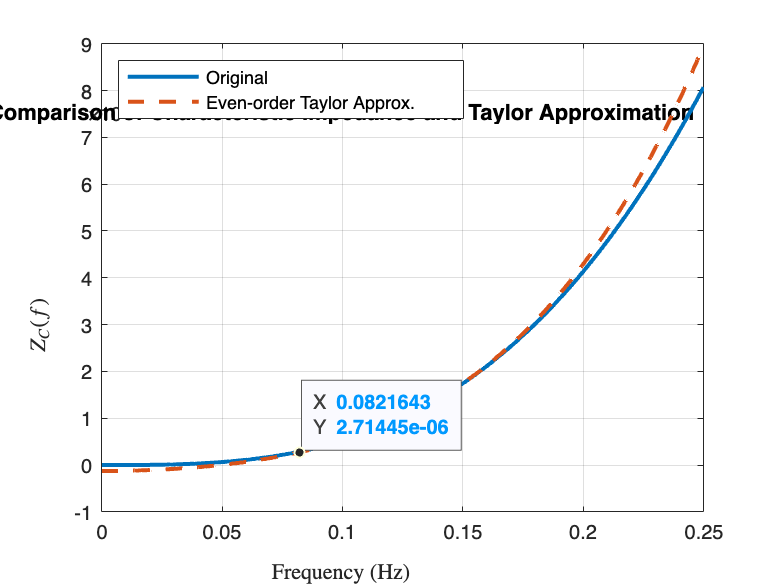


% Plotting
figure
plot(omega/(2*pi), Z_true, 'LineWidth', 2)
hold on
plot(omega/(2*pi), Z_approx, '--', 'LineWidth', 2)
xlabel('Frequency (Hz)', 'Interpreter', 'latex')
ylabel('$Z_C(f)$', 'Interpreter', 'latex')
legend('Original', 'Even-order Taylor Approx.', 'Location', 'northwest')
title('Comparison of Characteristic Impedance and Taylor Approximation')
grid on
hold off

## **Filter design**

Current SIL has pole around 0.309 rad/s = 0.0492 Hz. To counteract the over estimate transfer function, we need to design a filter that mitigate the spike at the pole. 

% Define notch filter parameters
omega_notch = abs(imag(poles(4)));    % rad/s
zeta = 0.05;            % narrow notch

% Numerator and denominator
Num = [1 0 omega_notch^2];
Den = [1 2*zeta*omega_notch omega_notch^2];

% Define the notch filter transfer function
notch_filter = tf(Num, Den);

% Plot notch filter Bode plot
figure
bodeplot(notch_filter);
title('Notch Filter at 0.309 rad/s');
grid on;


% Apply filter to the system
filtered_sys = notch_filter * sys;

% Bode plot comparison
figure
bodeplot(sys, filtered_sys);
legend("Original", "Filtered");
title('Bode Plot: Original vs. Notch Filtered');
grid on;